# Noise reduction using Non-negative Matrix Factorization

### Sound and Music Signal Analysis 

#### Simon Rostami Mosen, 20176458

This project demonstrates the usefulness of NMF in noise reduction. While this is an individual project, implementational discussion were taken with Oddur Kristjansson. 

The spectrogram of a signal can be estimated by summing the product of each dictionary atom and activation matrix entry, mathematically expressed below:

$$$
{S} \approx {D} {A}=\left[\begin{array}{lll}
{d}_{1} & \cdots & {d}_{K}
\end{array}\right]\left[\begin{array}{c}
{a}_{1}^{T} \\
\vdots \\
{a}_{K}^{T}
\end{array}\right]=\sum_{k=1}^{K} {d}_{k} {a}_{k}^{T}
$$$s

Where S is the spectrogram, D is the dictionary matrix and A is the activation matrix. 

## Importing files the individual piano keys and the noise signal

clear all; close all; clc;
%[xClean, Fs] = audioread('melodiak5_part.wav');

[xNoisy, Fs] = audioread('noisyMelody.wav');

[x1, Fs] = audioread('la4k5.wav');
[x2, Fs] = audioread('fa4k5.wav');
[x3, Fs] = audioread('do5k5.wav');
[x4, Fs] = audioread('sol4k5.wav');
[x5, Fs] = audioread('re#5k5.wav');
[x6, Fs] = audioread('si4k5.wav');
[x7, Fs] = audioread('la#4k5.wav');
[x8, Fs] = audioread('re5k5.wav');

[xNoise, Fs2] = audioread('mainsBrum50Hz.wav');

## Setting up variables for sparse STFT

The first step in this process is to create our dictionary of atoms based on the recorded piano keys (x1...x8).  


segmentTime = 0.035;
segmentLength = round(segmentTime*Fs);
specWindow = hann(segmentLength, 'periodic');
% specWindow = ones(segmentLength,1);
nDft = 4096;
nOverlap = 0.5*segmentLength;
maxDynRange = 60;
lambda = 0.01;

## Using the sparseStft function to calculate S, F and T values.

%[sparseS, sparseF, sparseT] = sparseStft(xClean, specWindow, nOverlap, nDft, Fs, lambda);
[sparseSNoisy, sparseFNoisy, sparseTNoisy] = sparseStft( ...
    xNoisy, specWindow, nOverlap, nDft, Fs, lambda);

Processing segment 10 of 1549
Processing segment 20 of 1549
Processing segment 30 of 1549
Processing segment 40 of 1549
Processing segment 50 of 1549
Processing segment 60 of 1549
Processing segment 70 of 1549
Processing segment 80 of 1549
Processing segment 90 of 1549
Processing segment 100 of 1549
Processing segment 110 of 1549
Processing segment 120 of 1549
Processing segment 130 of 1549
Processing segment 140 of 1549
Processing segment 150 of 1549
Processing segment 160 of 1549
Processing segment 170 of 1549
Processing segment 180 of 1549
Processing segment 190 of 1549
Processing segment 200 of 1549
Processing segment 210 of 1549
Processing segment 220 of 1549
Processing segment 230 of 1549
Processing segment 240 of 1549
Processing segment 250 of 1549
Processing segment 260 of 1549
Processing segment 270 of 1549
Processing segment 280 of 1549
Processing segment 290 of 1549
Processing segment 300 of 1549
Processing segment 310 of 1549
Processing segment 320 of 1549
Processing segmen


[sparseS1, sparseF1, sparseT1] = sparseStft( ...
    x1, specWindow, nOverlap, nDft, Fs, lambda);

Processing segment 10 of 213
Processing segment 20 of 213
Processing segment 30 of 213
Processing segment 40 of 213
Processing segment 50 of 213
Processing segment 60 of 213
Processing segment 70 of 213
Processing segment 80 of 213
Processing segment 90 of 213
Processing segment 100 of 213
Processing segment 110 of 213
Processing segment 120 of 213
Processing segment 130 of 213
Processing segment 140 of 213
Processing segment 150 of 213
Processing segment 160 of 213
Processing segment 170 of 213
Processing segment 180 of 213
Processing segment 190 of 213
Processing segment 200 of 213
Processing segment 210 of 213


[sparseS2, sparseF2, sparseT2] = sparseStft( ...
    x2, specWindow, nOverlap, nDft, Fs, lambda);

Processing segment 10 of 220
Processing segment 20 of 220
Processing segment 30 of 220
Processing segment 40 of 220
Processing segment 50 of 220
Processing segment 60 of 220
Processing segment 70 of 220
Processing segment 80 of 220
Processing segment 90 of 220
Processing segment 100 of 220
Processing segment 110 of 220
Processing segment 120 of 220
Processing segment 130 of 220
Processing segment 140 of 220
Processing segment 150 of 220
Processing segment 160 of 220
Processing segment 170 of 220
Processing segment 180 of 220
Processing segment 190 of 220
Processing segment 200 of 220
Processing segment 210 of 220
Processing segment 220 of 220


[sparseS3, sparseF3, sparseT3] = sparseStft( ...
    x3, specWindow, nOverlap, nDft, Fs, lambda);

Processing segment 10 of 220
Processing segment 20 of 220
Processing segment 30 of 220
Processing segment 40 of 220
Processing segment 50 of 220
Processing segment 60 of 220
Processing segment 70 of 220
Processing segment 80 of 220
Processing segment 90 of 220
Processing segment 100 of 220
Processing segment 110 of 220
Processing segment 120 of 220
Processing segment 130 of 220
Processing segment 140 of 220
Processing segment 150 of 220
Processing segment 160 of 220
Processing segment 170 of 220
Processing segment 180 of 220
Processing segment 190 of 220
Processing segment 200 of 220
Processing segment 210 of 220
Processing segment 220 of 220


[sparseS4, sparseF4, sparseT4] = sparseStft( ...
    x4, specWindow, nOverlap, nDft, Fs, lambda);

Processing segment 10 of 227
Processing segment 20 of 227
Processing segment 30 of 227
Processing segment 40 of 227
Processing segment 50 of 227
Processing segment 60 of 227
Processing segment 70 of 227
Processing segment 80 of 227
Processing segment 90 of 227
Processing segment 100 of 227
Processing segment 110 of 227
Processing segment 120 of 227
Processing segment 130 of 227
Processing segment 140 of 227
Processing segment 150 of 227
Processing segment 160 of 227
Processing segment 170 of 227
Processing segment 180 of 227
Processing segment 190 of 227
Processing segment 200 of 227
Processing segment 210 of 227
Processing segment 220 of 227


[sparseS5, sparseF5, sparseT5] = sparseStft( ...
    x5, specWindow, nOverlap, nDft, Fs, lambda);

Processing segment 10 of 237
Processing segment 20 of 237
Processing segment 30 of 237
Processing segment 40 of 237
Processing segment 50 of 237
Processing segment 60 of 237
Processing segment 70 of 237
Processing segment 80 of 237
Processing segment 90 of 237
Processing segment 100 of 237
Processing segment 110 of 237
Processing segment 120 of 237
Processing segment 130 of 237
Processing segment 140 of 237
Processing segment 150 of 237
Processing segment 160 of 237
Processing segment 170 of 237
Processing segment 180 of 237
Processing segment 190 of 237
Processing segment 200 of 237
Processing segment 210 of 237
Processing segment 220 of 237
Processing segment 230 of 237


[sparseS6, sparseF6, sparseT6] = sparseStft( ...
    x6, specWindow, nOverlap, nDft, Fs, lambda);

Processing segment 10 of 243
Processing segment 20 of 243
Processing segment 30 of 243
Processing segment 40 of 243
Processing segment 50 of 243
Processing segment 60 of 243
Processing segment 70 of 243
Processing segment 80 of 243
Processing segment 90 of 243
Processing segment 100 of 243
Processing segment 110 of 243
Processing segment 120 of 243
Processing segment 130 of 243
Processing segment 140 of 243
Processing segment 150 of 243
Processing segment 160 of 243
Processing segment 170 of 243
Processing segment 180 of 243
Processing segment 190 of 243
Processing segment 200 of 243
Processing segment 210 of 243
Processing segment 220 of 243
Processing segment 230 of 243
Processing segment 240 of 243


[sparseS7, sparseF7, sparseT7] = sparseStft( ...
    x7, specWindow, nOverlap, nDft, Fs, lambda);

Processing segment 10 of 248
Processing segment 20 of 248
Processing segment 30 of 248
Processing segment 40 of 248
Processing segment 50 of 248
Processing segment 60 of 248
Processing segment 70 of 248
Processing segment 80 of 248
Processing segment 90 of 248
Processing segment 100 of 248
Processing segment 110 of 248
Processing segment 120 of 248
Processing segment 130 of 248
Processing segment 140 of 248
Processing segment 150 of 248
Processing segment 160 of 248
Processing segment 170 of 248
Processing segment 180 of 248
Processing segment 190 of 248
Processing segment 200 of 248
Processing segment 210 of 248
Processing segment 220 of 248
Processing segment 230 of 248
Processing segment 240 of 248


[sparseS8, sparseF8, sparseT8] = sparseStft( ...
    x8, specWindow, nOverlap, nDft, Fs, lambda);

Processing segment 10 of 249
Processing segment 20 of 249
Processing segment 30 of 249
Processing segment 40 of 249
Processing segment 50 of 249
Processing segment 60 of 249
Processing segment 70 of 249
Processing segment 80 of 249
Processing segment 90 of 249
Processing segment 100 of 249
Processing segment 110 of 249
Processing segment 120 of 249
Processing segment 130 of 249
Processing segment 140 of 249
Processing segment 150 of 249
Processing segment 160 of 249
Processing segment 170 of 249
Processing segment 180 of 249
Processing segment 190 of 249
Processing segment 200 of 249
Processing segment 210 of 249
Processing segment 220 of 249
Processing segment 230 of 249
Processing segment 240 of 249



[sparseSNoise, sparseFNoise, sparseTNoise] = sparseStft( ...
    xNoise, specWindow, nOverlap, nDft, Fs2, lambda);

Processing segment 10 of 156
Processing segment 20 of 156
Processing segment 30 of 156
Processing segment 40 of 156
Processing segment 50 of 156
Processing segment 60 of 156
Processing segment 70 of 156
Processing segment 80 of 156
Processing segment 90 of 156
Processing segment 100 of 156
Processing segment 110 of 156
Processing segment 120 of 156
Processing segment 130 of 156
Processing segment 140 of 156
Processing segment 150 of 156


## Using nnmf function

This function is based on a code snippet from lecture 8. It is used to generate atoms for the dictionary based on the individial piano note recordings. 

The activation matrix variables (Ax) are discarded.

%%
[D1,A1, cost1] = nnmf(abs(sparseS1),1);
[D2,A2, cost2] = nnmf(abs(sparseS2),1);
[D3,A3, cost3] = nnmf(abs(sparseS3),1);
[D4,A4, cost4] = nnmf(abs(sparseS4),1);
[D5,A5, cost5] = nnmf(abs(sparseS5),1);
[D6,A6, cost6] = nnmf(abs(sparseS6),1);
[D7,A7, cost7] = nnmf(abs(sparseS7),1);
[D8,A8, cost8] = nnmf(abs(sparseS8),1);

[DNoise,ANoise, costNoise] = nnmf(abs(sparseSNoise),1);


Stitching together the dictionary matrix D and generating a random matrix A of size KxN for the 

D = [D1 D2 D3 D4 D5 D6 D7 D8 DNoise];
N = length(sparseTNoisy);
K = 9;
A = rand(K,N);


The dictionaries are plotted below:

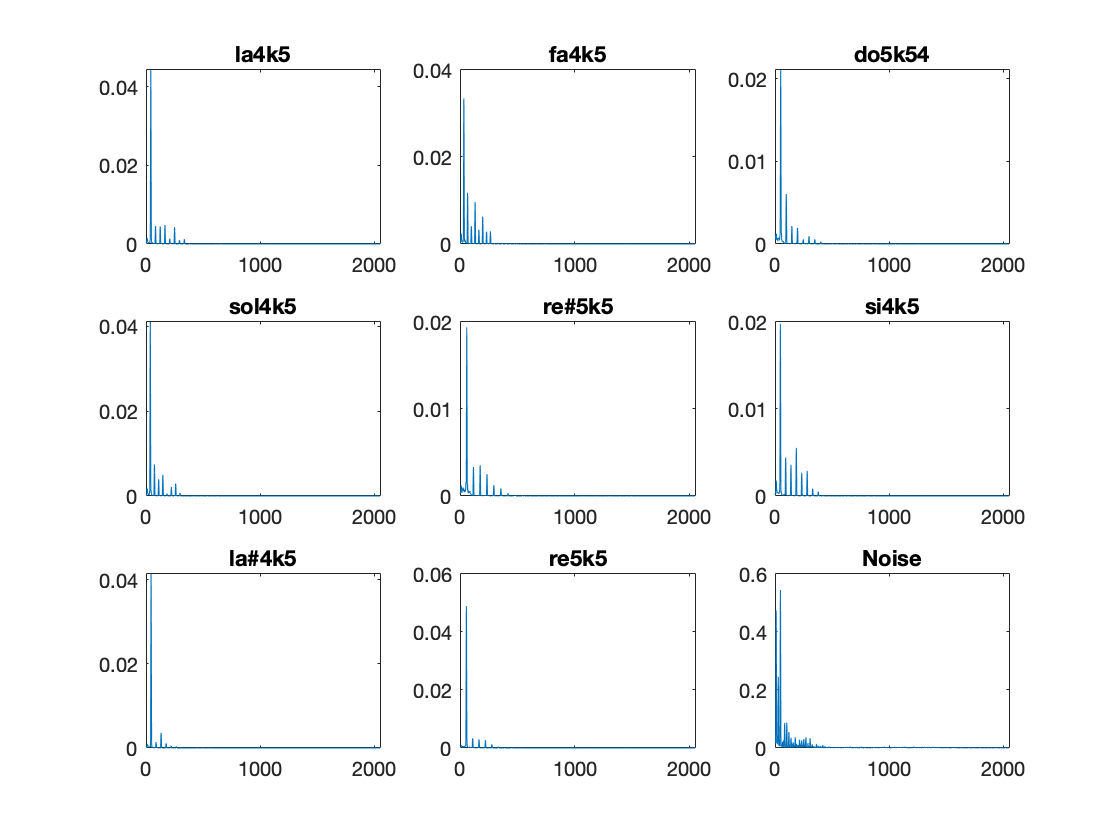

figure;
subplot(3,3,1);
plot(abs(D1)); title('la4k5');
subplot(3,3,2);
plot(abs(D2)); title('fa4k5');
subplot(3,3,3);
plot(abs(D3)); title('do5k54');
subplot(3,3,4);
plot(abs(D4)); title('sol4k5');
subplot(3,3,5);
plot(abs(D5)); title('re#5k5');
subplot(3,3,6);
plot(abs(D6)); title('si4k5');
subplot(3,3,7);
plot(abs(D7)); title('la#4k5');
subplot(3,3,8);
plot(abs(D8)); title('re5k5');
subplot(3,3,9);
plot(abs(DNoise)); title('Noise');

## Using Multiplicative Gradient Descent 

Multiplicative Gradient Descent is used to solve the optimization problem and thereby the activation matrix is found.


$$$$
d_{\beta}(x \mid y)=\left\{\begin{array}{ll}
\frac{1}{2}(x-y)^{2} & \beta=2 \\
x \log \frac{x}{y}+(y-x) & \beta=1 \\
\frac{x}{y}-\log \frac{x}{y}-1 & \beta=0
\end{array}\right.
$$$$


where 


$$$\beta=2$ Euclidean divergence
$\beta=1$ Kullback-Leibler (KL) divergence 
$\beta=0$ Itakura-Saito (IS) divergence$$


A beta value of 0 was decided which puts equal emphasis on small and big components. IS-NMF is sensitive to sidelobes and other artefacts. 

Multiplicative Gradient Descent is given by the following: 


$$$$
\begin{array}{l}
{D}={D} \odot\left[\left(({D} {A})^{\odot(\beta-2)} \odot {S}\right) {A}^{T}\right] \odot\left[({D} {A})^{\odot(\beta-1)} {A}^{T}\right]^{\odot-1} \\
{A}={A} \odot\left[{D}^{T}\left(({D} {A})^{\odot(\beta-2)} \odot {S}\right)\right] \odot\left[{D}^{T}({D} {A})^{\odot(\beta-1)}\right]^{\odot-1}
\end{array}
$$$$


where $\odot$ is element-wise multiplication. D and A should be normalized after each iteration. 

As I already have a dictionary (supervised NMF), the iteration of D as well as normalization in the Multiplicative Gradient Descent is skipped.

n_iter = 15;
beta = 2;

[D, A, cost] = beta_nmf_mu(abs(sparseSNoisy).^2, n_iter, D, A, beta);

From the Multiplicative Gradient Descent the activation matrix A was calculated. The activation matrices for each note is plotted below.

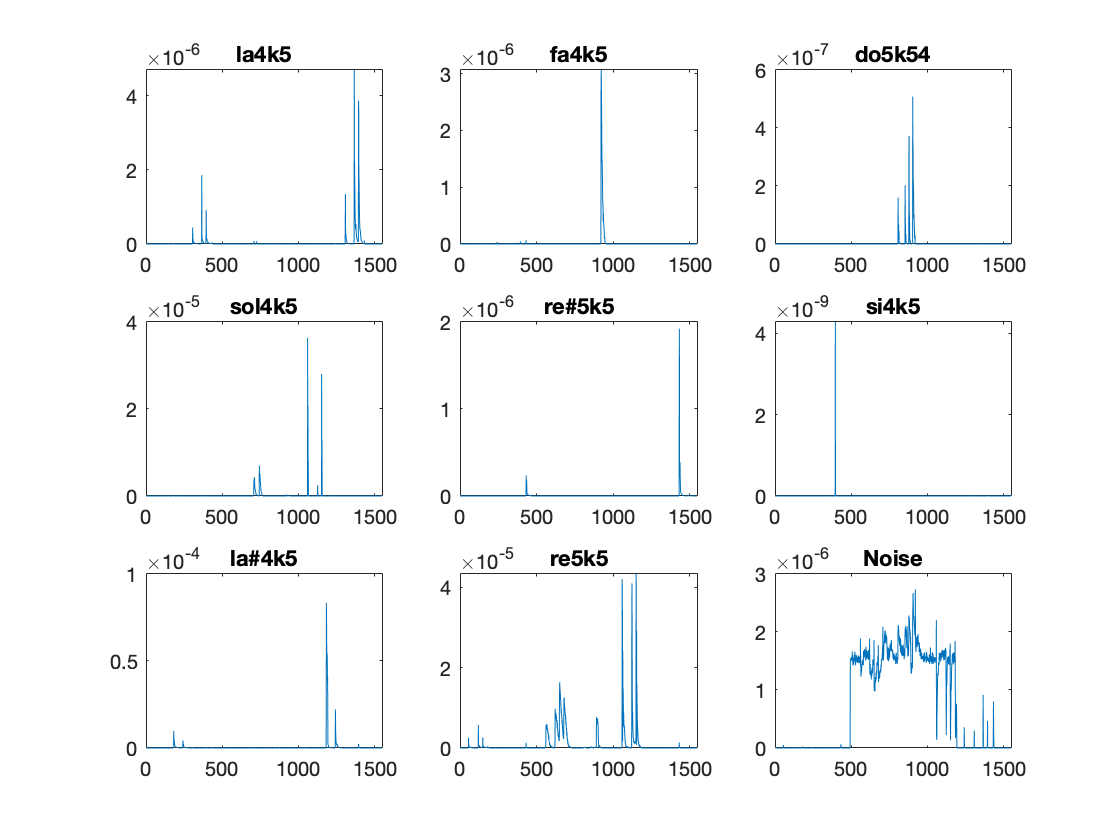

figure;
subplot(3,3,1);
plot(abs(A(1,:))); title('la4k5');
subplot(3,3,2);
plot(abs(A(2,:))); title('fa4k5');
subplot(3,3,3);
plot(abs(A(3,:))); title('do5k54');
subplot(3,3,4);
plot(abs(A(4,:))); title('sol4k5');
subplot(3,3,5);
plot(abs(A(5,:))); title('re#5k5');
subplot(3,3,6);
plot(abs(A(6,:))); title('si4k5');
subplot(3,3,7);
plot(abs(A(7,:))); title('la#4k5');
subplot(3,3,8);
plot(abs(A(8,:))); title('re5k5');
subplot(3,3,9);
plot(abs(A(9,:))); title('Noise');

## Reconstructing phase

As the phase information is lost in the deconstruction of the signal, Wiener filtering is used to reconstruct the phase. 

We can conisder our noisy signal x(n) as a mixture:


$$$$
x(n)=d(n)+u(n)
$$$$


where $d\left(n\right)\;$is the desired signal we want to extract and $u\left(n\right)$ is the component of the signal which we are not interested in.

This can be expressed in frequency domain by computing the DTFT of the signal:


$$$$
X(\omega)=D(\omega)+U(\omega)
$$$$


The frequency domain Wiener filter also called the Wiener gain can be estimated as follows.


$$$$
H(\omega) \approx \frac{|D(\omega)|^{2}}{|D(\omega)|^{2}+|U(\omega)|^{2}}
$$$$


I use NMF to find the power spectrum of the individual signal components and use the following equation to compute the Wiener gain.


$$$$
{X}_{k}=\left[{d}_{{k}} {a}_{{k}}^{T} \odot({D} {A})^{\odot-1}\right] \odot {X}
$$$$


X1 = ((D1*A(1,:)).*(D*A).^(-1)).*sparseSNoisy;
X2 = ((D2*A(2,:)).*(D*A).^(-1)).*sparseSNoisy;
X3 = ((D3*A(3,:)).*(D*A).^(-1)).*sparseSNoisy;
X4 = ((D4*A(4,:)).*(D*A).^(-1)).*sparseSNoisy;
X5 = ((D5*A(5,:)).*(D*A).^(-1)).*sparseSNoisy;
X6 = ((D6*A(6,:)).*(D*A).^(-1)).*sparseSNoisy;
X7 = ((D7*A(7,:)).*(D*A).^(-1)).*sparseSNoisy;
X8 = ((D8*A(8,:)).*(D*A).^(-1)).*sparseSNoisy;


The wiener gain of each atom of the dictionary/piano is then summed together to one matrix.

XCombined = X1 + X2 + X3 + X4 + X5 + X6 + X7 + X8;


## Inverse STFT

To go back to time domain, Inverse STFT is used. The variable values are identical to the one used in the sparseSTFT earlier.

iy = istft(XCombined, Fs, 'Window', specWindow, 'OverlapLength', nOverlap, 'FFTLength', nDft);


A loud peak irelevant to signal was found in the very beginning and very end of the signal, why it was cut in each end.

iy = iy(10:1000000);
out = abs(iy);


A plot of the time domain signal is seen below.

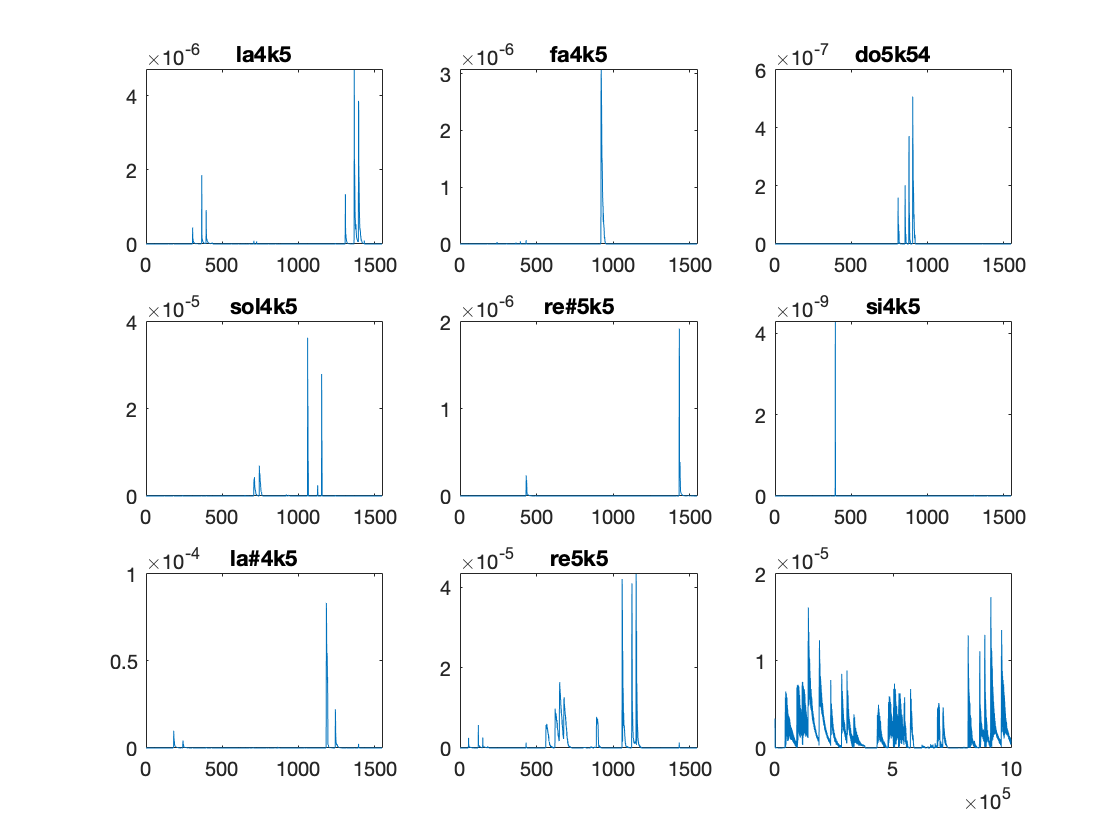

plot(out);

The noise reduced audio is played back below.

soundsc(out,Fs);


## Audiowrite

% -20dB for audiowrite, uncomment below if you want to generate a .wav file.

 R_dB = -20;
R = 10^(R_dB/20);
a = sqrt((length(out)*R^2)/(sum(out.^2)));

out = out*a;
audiowrite('noiseReduced.wav', out, Fs);


## Spectrograms of observed signal and 

A spectrogram of the observed signal with piano melody and noise is seen below.

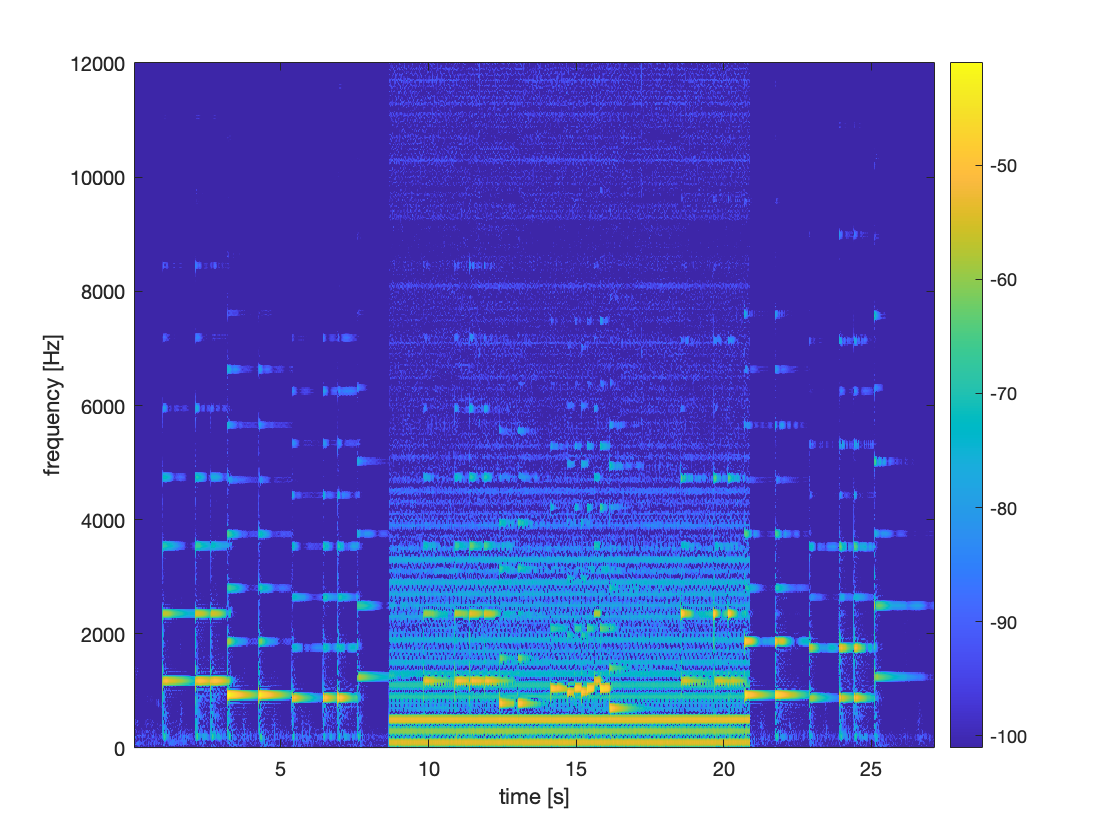

figure
imagesc(sparseTNoisy,sparseFNoisy,...
    10*log10(dynamicRangeLimiting(abs(sparseSNoisy).^2, maxDynRange)))
set(gca,'YDir','normal')
xlabel('time [s]')
ylabel('frequency [Hz]')
ylim([0 1.2*10^4]);
colorbar

A spectrogram of the noise reduced signal is seen below. 

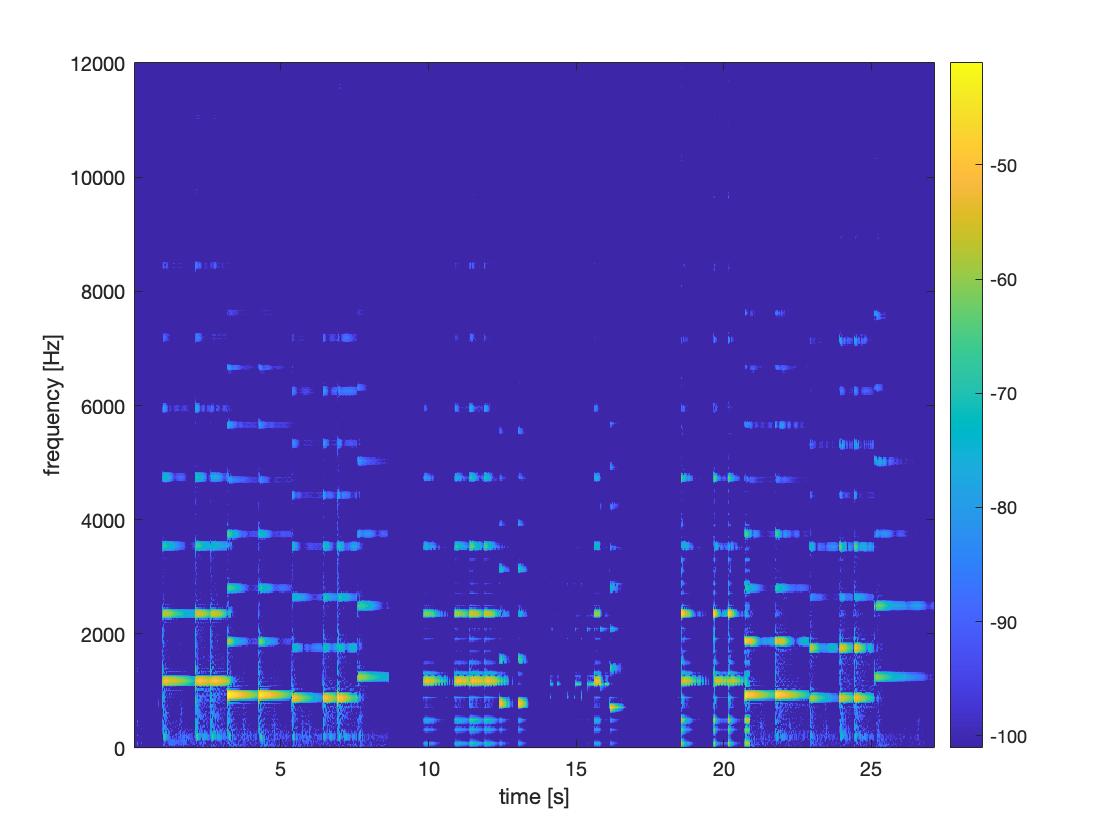

figure
imagesc(sparseTNoisy,sparseFNoisy,...
    10*log10(dynamicRangeLimiting(abs(XCombined).^2, maxDynRange)))
set(gca,'YDir','normal')
xlabel('time [s]')
ylabel('frequency [Hz]')
ylim([0 1.2*10^4]);
colorbar

## Findings

NMF can be used to remove/reduce noise from recordings. As seen on the last spectrogram it is difficult to remove all noise, while still keeping the spectral complexity of the signal intact. 